# **MATLAB Assignment 3**

# Continuous and Discrete Wavelet Transforms 

**S.S. Hettiarachchi**

**180237G **

**BME**

## **II. Discrete Wavelet Transform**

**2.2.Applying DWT with the Wavelet Toolbox in MATLAB**

clearvars; close all; clc;
fs = 512;

n_1 = 0:1:512-1;  % For the first half of the signal
n_2 = 512:1:1023; % For the second half of the signal


% Creating sinasoidal X1 signal
x_1 = [(2*sin(20*pi*n_1/fs) + sin(80*pi*n_1/fs))  (0.5*sin(40*pi*n_2/fs) + sin(60*pi*n_2/fs))];


% 1024 sample length array
x_2 = zeros(1, 1024); 

% Creating X2 signal
for j = 0:1023
    if (j >= 0 &&  j<64)
        x_2(j+1) = 1;
    elseif (j >= 192 &&  j<256)
        x_2(j+1) = 2;
    elseif (j >= 256 &&  j<512)
        x_2(j+1) = -1;
    elseif (j >= 512 &&  j<704)
        x_2(j+1) = 3;
    elseif (j >= 704 &&  j<960)
        x_2(j+1) = 1;
    else
        x_2(j+1)=0;
    end
end

% Addign additive white gaussian noise to x_1 and x_2 signal (10dB)
y_1 = awgn(x_1, 10,'measured');
y_2 = awgn(x_2, 10,'measured');

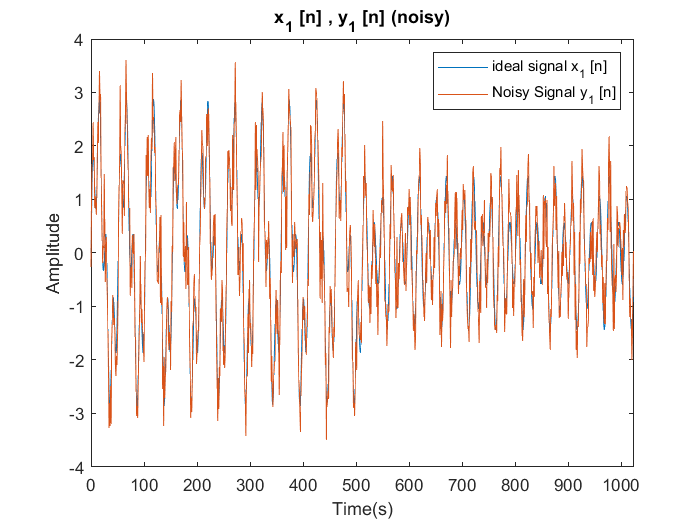

% Plotting x_1[n] and y_1[n] signal in time domain
figure;
plot([n_1 n_2], x_1, [n_1 n_2], y_1);
legend('ideal signal x_1 [n]', 'Noisy Signal y_1 [n]'),
title('x_1 [n] , y_1 [n] (noisy)');
xlabel('Time(s)');
ylabel('Amplitude');
xlim([0 1024]);

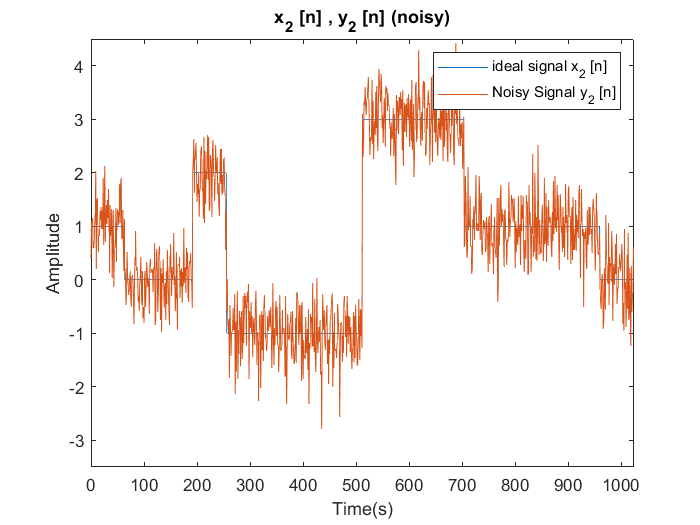

% Plotting x_2[n] and y_2[n] signal in time domain
figure;
plot([n_1 n_2], x_2, [n_1 n_2], y_2);
legend('ideal signal x_2 [n]', 'Noisy Signal y_2 [n]'),
title('x_2 [n] , y_2 [n] (noisy)');
xlabel('Time(s)');
ylabel('Amplitude');
axis([0 1024 -3.5 4.5]);

Observe the morphology of the wavelet and scaling functions of Haar and Daubechies tap 9 using wavefun() command and the waveletAnalyzer GUI.

10 iterations

**Harr Wavelet**

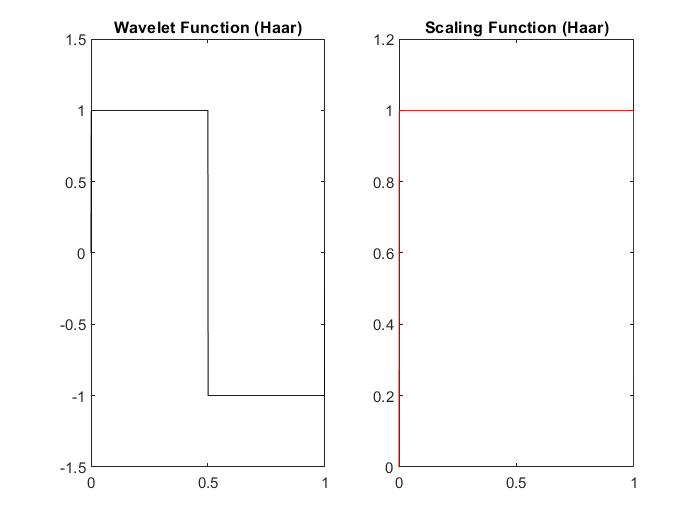

% phi_harr: Scaling function approximation of harr wavelet
% psi_haar: Wavelet approximation of harr wavelet
% xval_haar: Grid points where the wavelet and scaling function approximations are evaluated

[phi_haar, psi_haar, xval_haar] = wavefun('haar', 10); 
figure;
subplot(1,2,1);
plot(xval_haar, psi_haar,'black');
title('Wavelet Function (Haar)');
subplot(1,2,2);
plot(xval_haar, phi_haar,'red');
title('Scaling Function (Haar)');

**DB9 Wavelet **

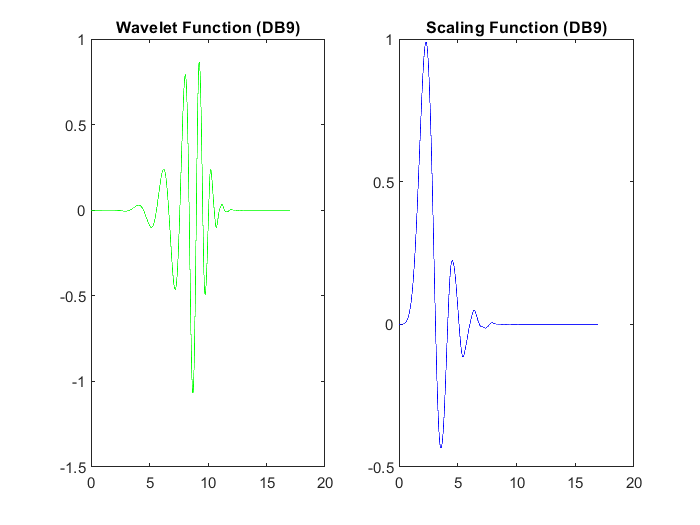

% phi_db9: Scaling function approximation of db9 wavelet
% psi_db9: Wavelet approximation of db9 wavelet
% xval_db9: Grid points where the wavelet and scaling function approximations are evaluated
[phi_db9,psi_db9, xval_db9] = wavefun('db9', 10); 
figure;
subplot(1,2,1);
plot(xval_db9, psi_db9,'green');
title('Wavelet Function (DB9)');
subplot(1,2,2);
plot(xval_db9, phi_db9,'blue');
title('Scaling Function (DB9)');

 **Calculate the 10-level wavelet decomposition of the signal using wavelet ‘db9’ and ‘haar’. Use the command wavedec()**

**Signal: **y_1 signal

**Wavelet:  **Harr wavelet

**#levels for decomposition: **10

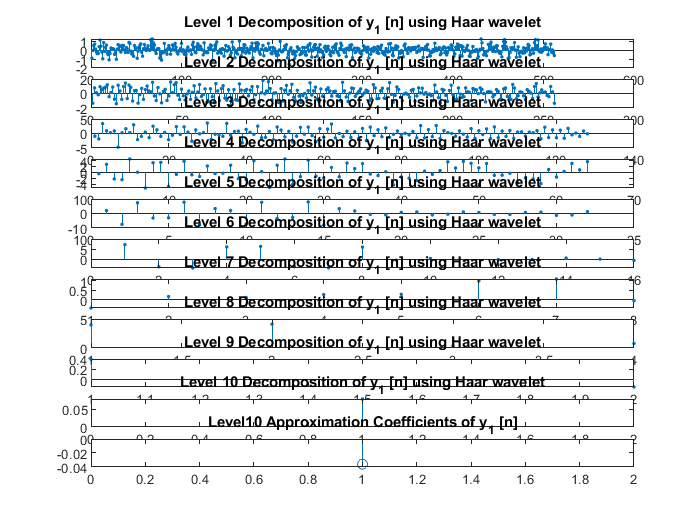

% c_haar_y_1: Wavelet decomposition vector
% l_haar_y_1: Bookkeeping vector
[c_haar_y_1, l_haar_y_1] = wavedec(y_1, 10, 'haar');

% For approximation coefficients
A_harr_y1 = appcoef(c_haar_y_1, l_haar_y_1, 'haar'); 
% For detail coefficients
[Dharr_11,Dharr_12,Dharr_13,Dharr_14,Dharr_15,Dharr_16,Dharr_17,Dharr_18,Dharr_19,Dharr_110] = detcoef(c_haar_y_1, l_haar_y_1, [1 2 3 4 5 6 7 8 9 10]);

% Plotting the detail coefficients
figure;
for j= 1:10
    D_harr_y1 = detcoef(c_haar_y_1, l_haar_y_1, j);
    subplot(11,1,j);
    stem(D_harr_y1,'Marker','.');
    title(['Level ' num2str(j) ' Decomposition of y_1 [n] using Haar wavelet']);
end

% Plotting approximationa coefficients
subplot(11,1,11);
stem(A_harr_y1);
title(['Level' num2str(10) ' Approximation Coefficients of y_1 [n]']);

**Signal: **y_1 signal

**Wavelet: ** Daubechies tap 9 Wavelet

**#levels for decomposition: **10

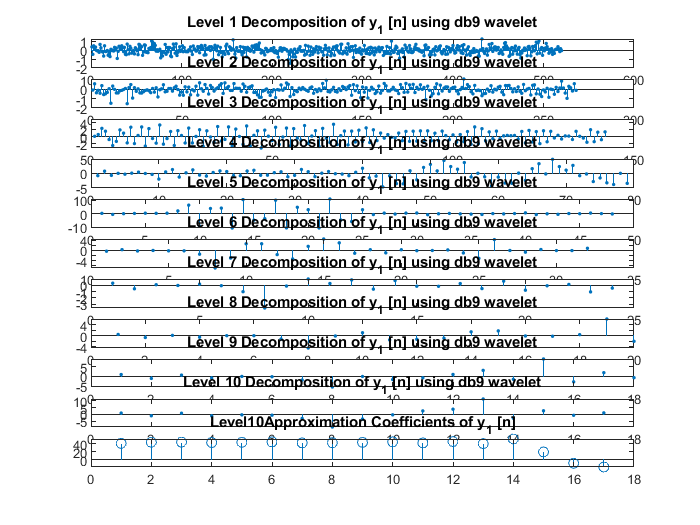

% c_db9_y1: Wavelet decomposition vector
% l_db9_y1: Bookkeeping vector
[c_db9_y1, l_db9_y1] = wavedec(y_1, 10, 'db9');

% For approximation coefficients
A_db9_y1 = appcoef(c_db9_y1, l_db9_y1, 'db9');
% For detail coefficients
[Ddb9_11,Ddb9_12,Ddb9_13,Ddb9_14,Ddb9_15,Ddb9_16,Ddb9_17,Ddb9_18,Ddb9_19,Ddb9_110] = detcoef(c_db9_y1, l_db9_y1, [1 2 3 4 5 6 7 8 9 10]);

% For detail coefficients
figure;
for j= 1:10
    D_db9_y1 = detcoef(c_db9_y1, l_db9_y1, j);
    subplot(11,1,j);
    stem(D_db9_y1,'Marker','.');
    title(['Level ' num2str(j) ' Decomposition of y_1 [n] using db9 wavelet']);
end

% Plotting approximation coefficients
subplot(11,1,11);
stem(A_db9_y1);
title(['Level' num2str(10) 'Approximation Coefficients of y_1 [n]']);

**Signal: **y_2 signal

**Wavelet: ** Haar Wavelet

**#levels for decomposition: **10

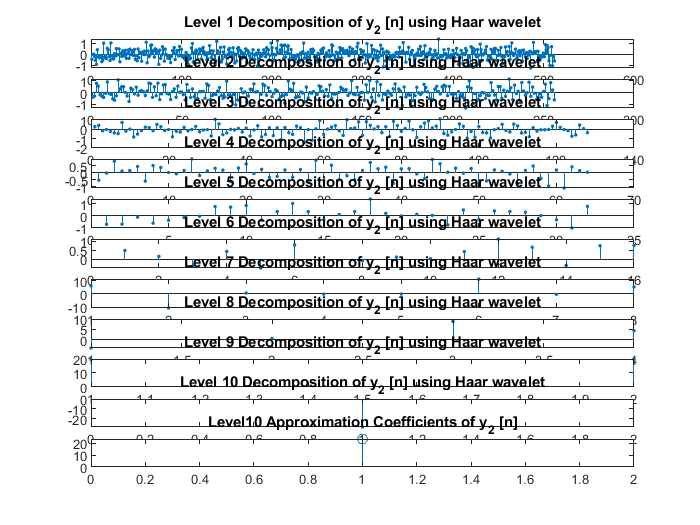

% c_haar_y_2: Wavelet decomposition vector
% l_haar_y_2: Bookkeeping vector
[c_haar_y2, l_haar_y2] = wavedec(y_2, 10, 'haar'); 

% For approximation corifccents
A_harr_y2 = appcoef(c_haar_y2, l_haar_y2, 'haar'); 
% For detail corifccents
[Dharr_21,Dharr_22,Dharr_23,Dharr_24,Dharr_25,Dharr_26,Dharr_27,Dharr_28,Dharr_29,Dharr_210] = detcoef(c_haar_y2, l_haar_y2, [1 2 3 4 5 6 7 8 9 10]);

% Plotting detail coeffcents
figure;
for j= 1:10
    D_harr_y2 = detcoef(c_haar_y2, l_haar_y2, j);
    subplot(11,1,j);
    stem(D_harr_y2,'Marker','.');
    title(['Level ' num2str(j) ' Decomposition of y_2 [n] using Haar wavelet']);
end

% Plotting approximation coefficients
subplot(11,1,11);
stem(A_harr_y2);
title(['Level' num2str(10) ' Approximation Coefficients of y_2 [n]']);

**Signal: **y_2 signal

**Wavelet: ** Daubechies tap 9 Wavelet

**#levels for decomposition: **10

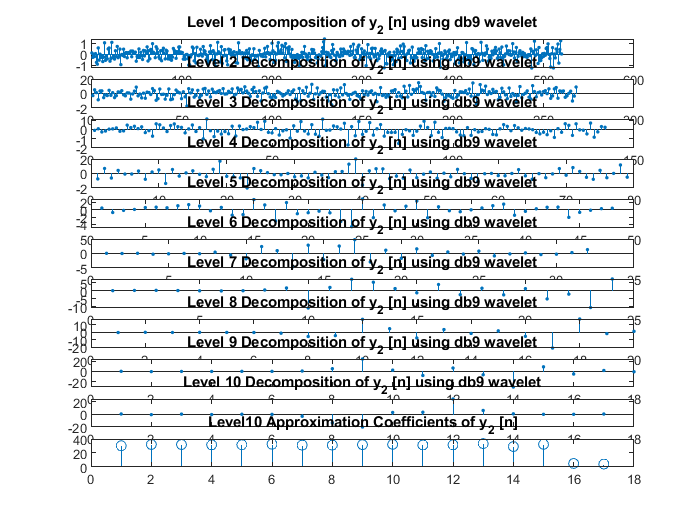

% c_db9_y2: Wavelet decomposition vector
% l_db9_y2: Bookkeeping vector
[c_db9_y2, l_db9_y2] = wavedec(y_2, 10, 'db9');

% For approximation corifccents
A_db9_y2 = appcoef(c_db9_y2, l_db9_y2, 'db9');
% For detail corifccents
[Ddb9_21,Ddb9_22,Ddb9_23,Ddb9_24,Ddb9_25,Ddb9_26,Ddb9_27,Ddb9_28,Ddb9_29,Ddb9_210] = detcoef(c_db9_y2, l_db9_y2, [1 2 3 4 5 6 7 8 9 10]);

% Plotting detail coefficients
figure;
for j= 1:10
    D_db9_y2 = detcoef(c_db9_y2, l_db9_y2, j);
    subplot(11,1,j);
    stem(D_db9_y2,'Marker','.');
    title(['Level ' num2str(j) ' Decomposition of y_2 [n] using db9 wavelet']);
end

% Plotting approximatioon coefficients
subplot(11,1,11);
stem(A_db9_y2);
title(['Level' num2str(10) ' Approximation Coefficients of y_2 [n]']);

## **Discrete Wave Resconstruction**

**x1 signal reconstruction**

**Wavelet: ** Haar waveltes

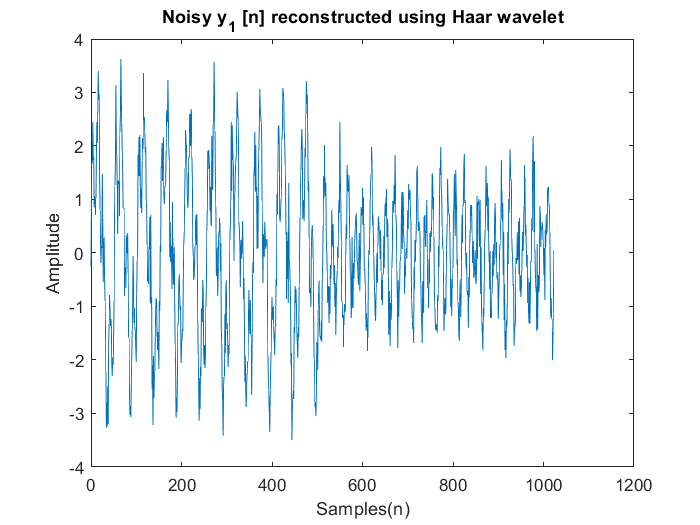

x_1_haar_rec = wave_reconstruction('haar',A_harr_y1,Dharr_11,Dharr_12,Dharr_13,Dharr_14,Dharr_15,Dharr_16,Dharr_17,Dharr_18,Dharr_19,Dharr_110);

figure;
plot(0:1023, x_1_haar_rec);
title('Noisy y_1 [n] reconstructed using Haar wavelet');
xlabel('Samples(n)');
ylabel('Amplitude');

**x1 signal reconstruction**

**Wavelet: ** DB9 waveltes

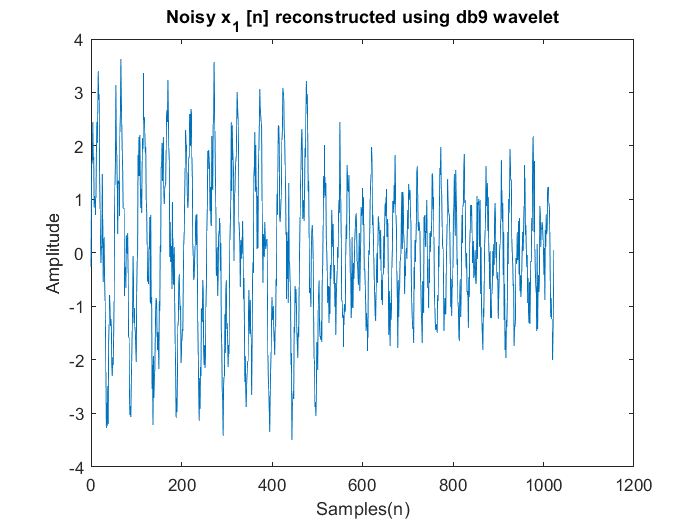

x_1_db9_rec = wave_reconstruction('db9',A_db9_y1,Ddb9_11,Ddb9_12,Ddb9_13,Ddb9_14,Ddb9_15,Ddb9_16,Ddb9_17,Ddb9_18,Ddb9_19,Ddb9_110);

figure;
plot(0:1023, x_1_db9_rec);
title('Noisy x_1 [n] reconstructed using db9 wavelet');
xlabel('Samples(n)');
ylabel('Amplitude');

**x2 signal reconstruction**

**Wavelet: ** Haar waveltes

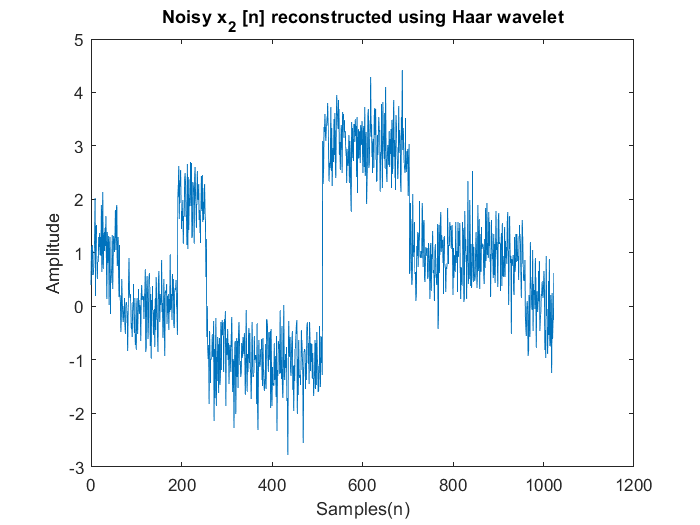

x_2_haar_rec = wave_reconstruction('haar',A_harr_y2,Dharr_21,Dharr_22,Dharr_23,Dharr_24,Dharr_25,Dharr_26,Dharr_27,Dharr_28,Dharr_29,Dharr_210);

figure;
plot(0:1023, x_2_haar_rec);
title('Noisy x_2 [n] reconstructed using Haar wavelet');
xlabel('Samples(n)');
ylabel('Amplitude');

**x1 signal reconstruction**

**Wavelet: ** DB9 wavelet

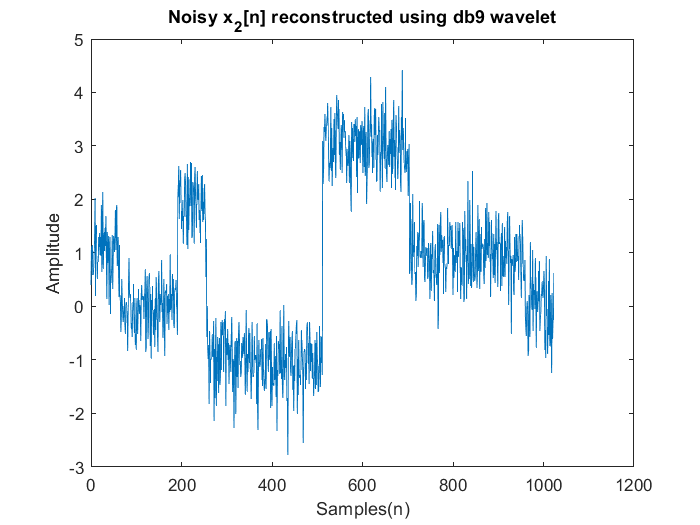

x_2_db9_rec = wave_reconstruction('db9',A_db9_y2,Ddb9_21,Ddb9_22,Ddb9_23,Ddb9_24,Ddb9_25,Ddb9_26,Ddb9_27,Ddb9_28,Ddb9_29,Ddb9_210);

figure;
plot(0:1023, x_2_db9_rec);
title('Noisy x_2[n] reconstructed using db9 wavelet');
xlabel('Samples(n)');
ylabel('Amplitude');

**Energy Calculation of the Reconstructed signals and original signals**

%y1
% ideal signal energy
E_y_1 = sum(abs(y_1).^2);
% Recostructed signal Energy (harr wavelet)
E_y_1_haar = sum(abs(x_1_haar_rec).^2);
% Recostructed signal Energy (db9 wavelet)
E_y_1_db9 = sum(abs(x_1_db9_rec).^2);

%y2
% ideal signal energy
E_y_2 = sum(abs(y_2).^2);
% Recostructed signal Energy (harr wavelet)
E_y_2_haar = sum(abs(x_2_haar_rec).^2);
% Recostructed signal Energy (db9 wavelet)
E_y_2_db9 = sum(abs(x_2_db9_rec).^2);


disp(['E(y_1) = ', num2str(E_y_1)]);

E(y_1) = 1834.3061


disp(['E(Reconstructed y_1 | haar wavelet) = ', num2str(E_y_1_haar)]);

E(Reconstructed y_1 | haar wavelet) = 1834.3061


disp(['E(Reconstructed y_1 | db9 wavelet) = ', num2str(E_y_1_db9)]);

E(Reconstructed y_1 | db9 wavelet) = 1834.3061


disp (' ')

disp(['E(y_2) = ', num2str(E_y_2)]);

E(y_2) = 2788.7725


disp(['E(Reconstructed y_2 | haar wavelet) = ', num2str(E_y_2_haar)]);

E(Reconstructed y_2 | haar wavelet) = 2788.7725


disp(['E(Reconstructed y_2 | db9 wavelet) = ', num2str(E_y_2_db9)]);

E(Reconstructed y_2 | db9 wavelet) = 2788.7725


## **2.3. Signal Denoising with DWT**

**Threshold = 1**

**Harr Wavelet for x1 signal**

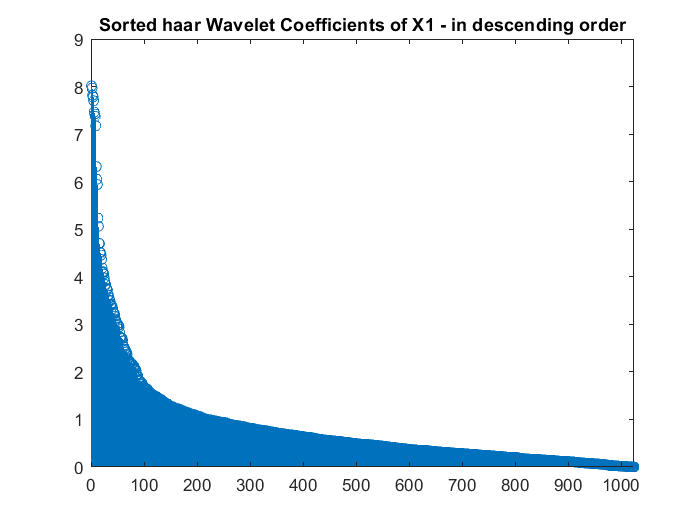

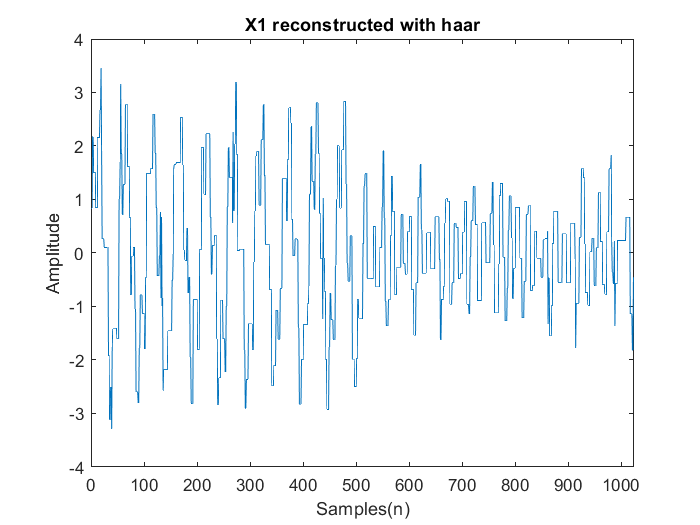

RMSE of X1 reconstructed with haar wavelet = 0.42843


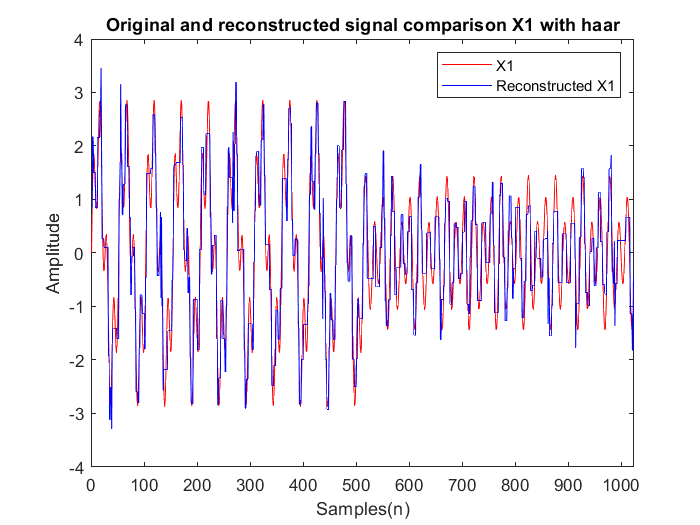

signal_denoising(x_1, y_1, 10, 'haar' , 1, 'X1');

**Threshold = 1**

**DB9 Wavelet for x1 signal**

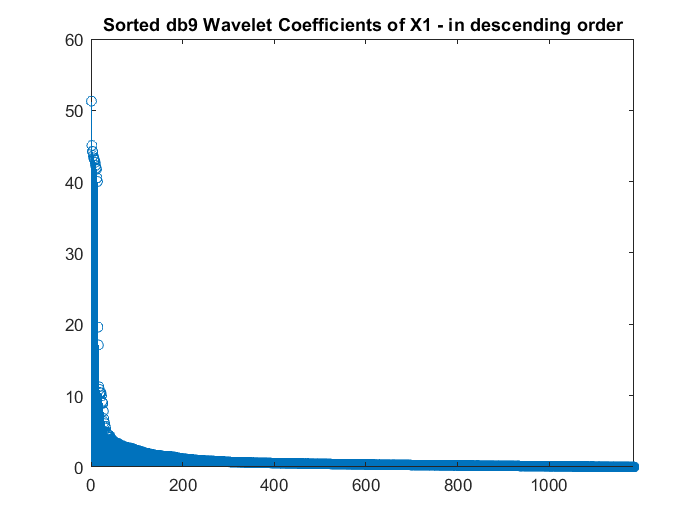

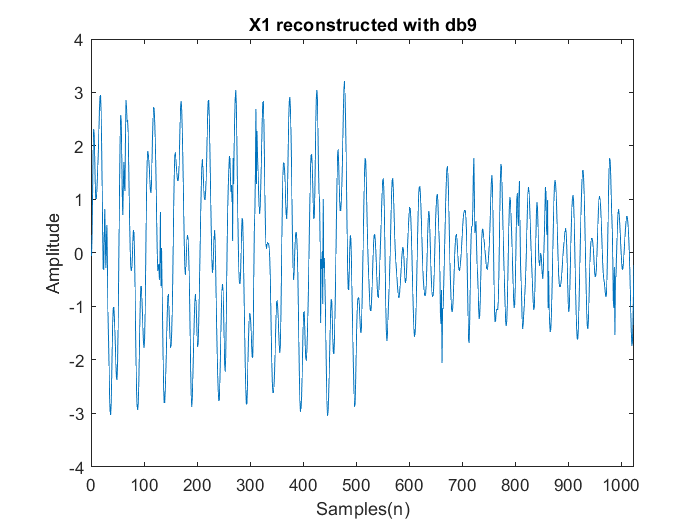

RMSE of X1 reconstructed with db9 wavelet = 0.26131


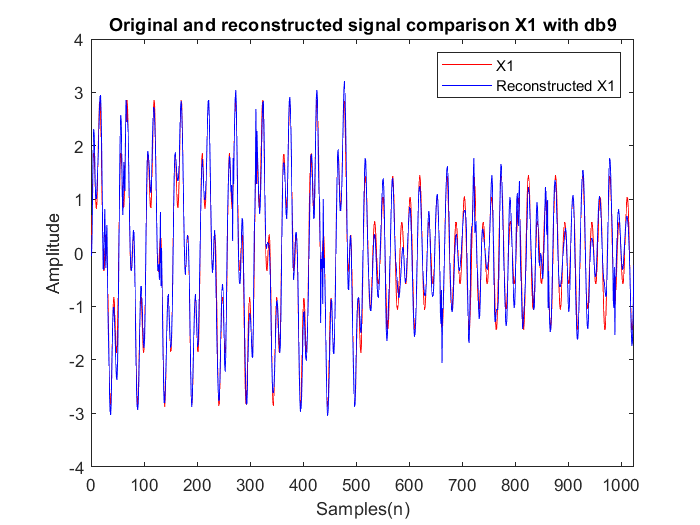

signal_denoising(x_1, y_1, 10, 'db9', 1, 'X1');

**Threshold = 1**

**Harr Wavelet for x2 signal**

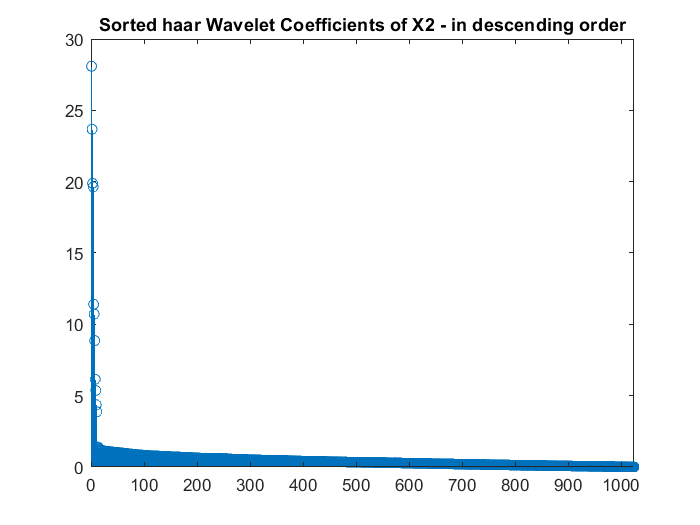

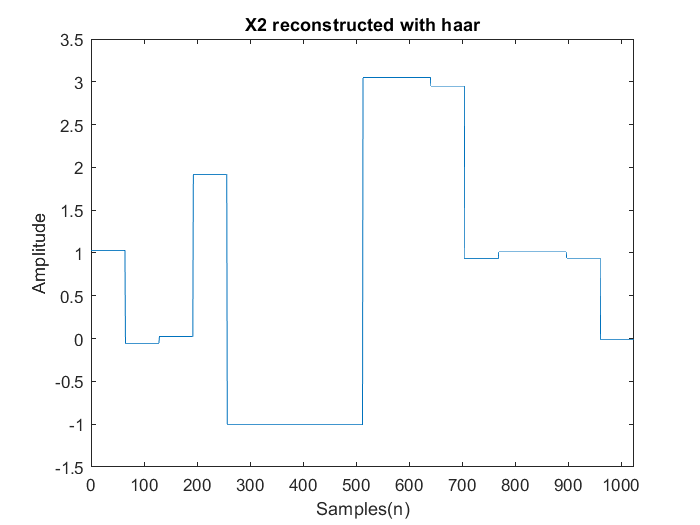

RMSE of X2 reconstructed with haar wavelet = 0.041098


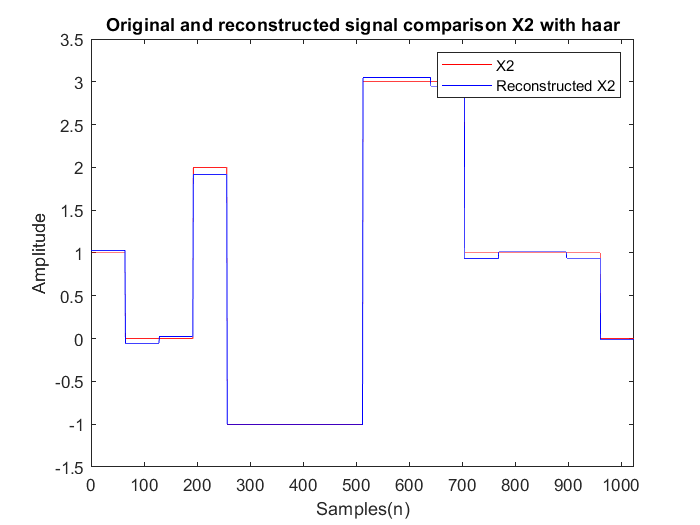

signal_denoising(x_2, y_2, 10, 'haar' , 2, 'X2');

**Threshold = 1**

**DB9 Wavelet for x2 signal**

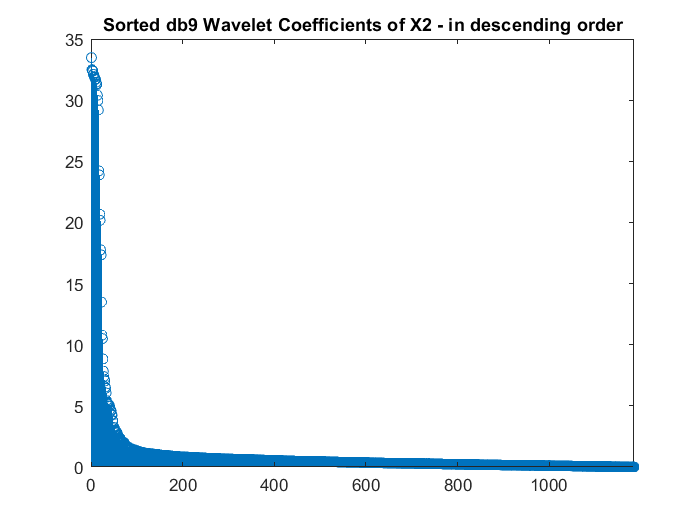

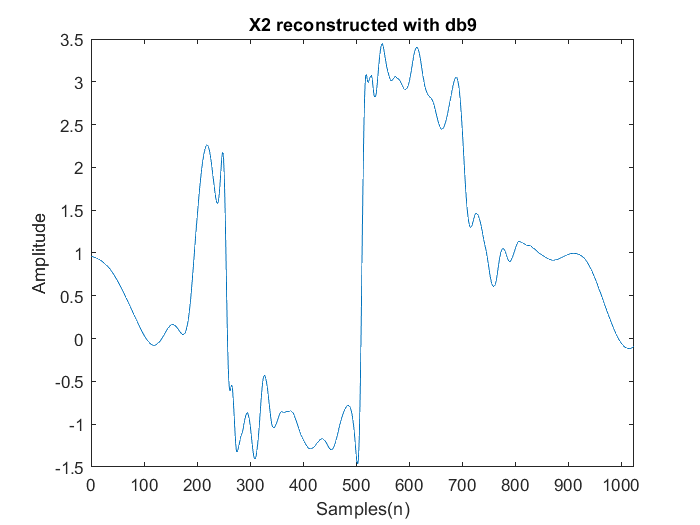

RMSE of X2 reconstructed with db9 wavelet = 0.2867


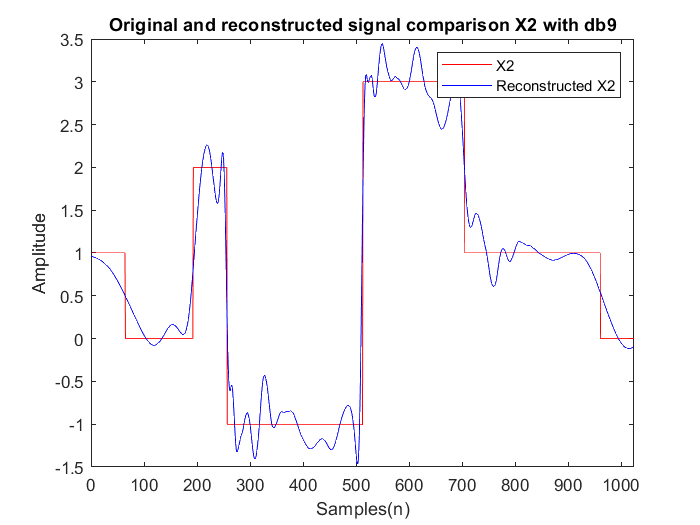

signal_denoising(x_2, y_2, 10, 'db9', 2, 'X2');

## 2.4. Signal Compression with DWT

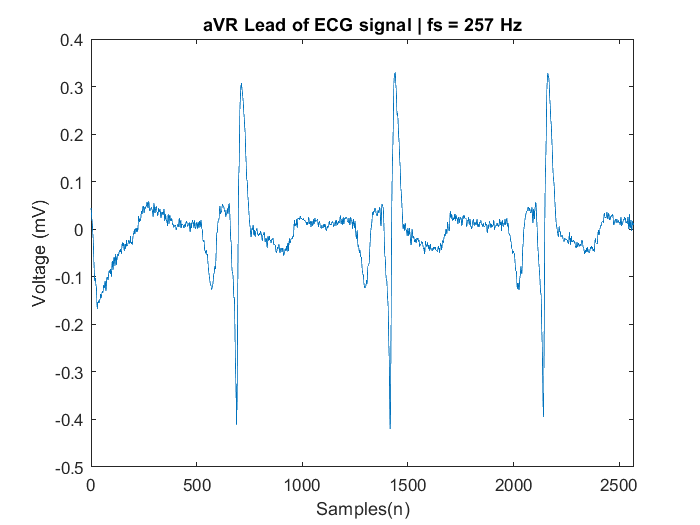

% Loading the ideal ECG signal 
load('ECGsig.mat');                     
signal_length = length(aVR);

% sampling freqency of the ECG
Fs = 257; 

% Number of samples
n  = 0:1:(signal_length-1);                   

figure('Name', 'aVR Lead of ECG signal | fs = 257 Hz');
plot(n, aVR);
title('aVR Lead of ECG signal | fs = 257 Hz'), xlabel('Samples(n)'), ylabel('Voltage (mV)');
xlim([0 length(aVR)]);

**Obtaining wavelet coefficients of aVR**

**Haar Wavelet **

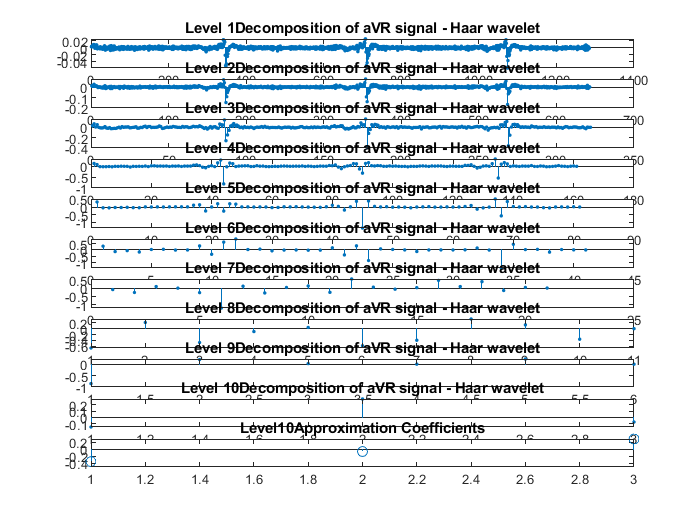


[c_haar_aVR, l_haar_aVR] = wavedec(aVR, 10, 'haar');
approx_haar_avr = appcoef(c_haar_aVR, l_haar_aVR, 'haar');

figure('Name', 'Decomposition of aVR signal - Haar wavelet');
for j= 1:10
    haarD_avr = detcoef(c_haar_aVR, l_haar_aVR, j);
    subplot(11,1,j);
    stem(haarD_avr,'Marker','.');
    title(['Level ' num2str(j) 'Decomposition of aVR signal - Haar wavelet']);
end
subplot(11,1,11);
stem(approx_haar_avr);
title(['Level' num2str(10) 'Approximation Coefficients']);

**DB9 Wavelet**

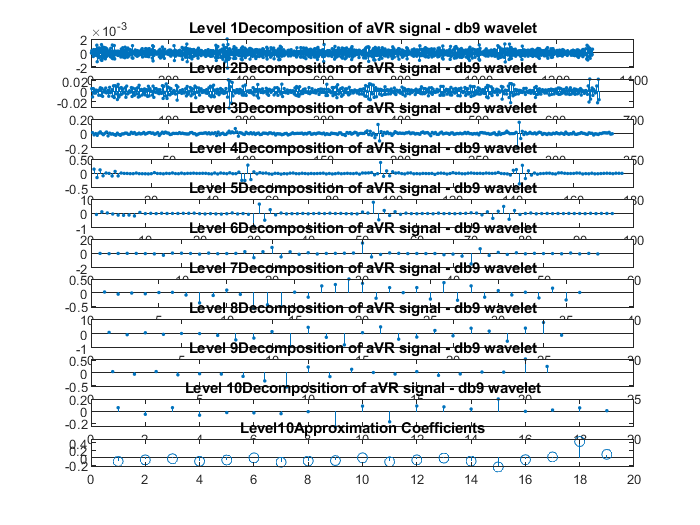

[c_db9_aVR, l_db9_avr] = wavedec(aVR, 10, 'db9');
approx_db_avr = appcoef(c_db9_aVR, l_db9_avr, 'db9');

figure('Name', 'Decomposition of aVR signal - db9 wavelet');
for j= 1:10
    dbD_avr = detcoef(c_db9_aVR, l_db9_avr, j);
    subplot(11,1,j);
    stem(dbD_avr,'Marker','.');
    title(['Level ' num2str(j) 'Decomposition of aVR signal - db9 wavelet']);
end
subplot(11,1,11);
stem(approx_db_avr);
title(['Level' num2str(10) 'Approximation Coefficients']);

**Signal Compression part**

level = ceil(log2(signal_length));
percentage = 99;

**Haar Wavelets for aVR signal**

**threshold 0 -> compression**

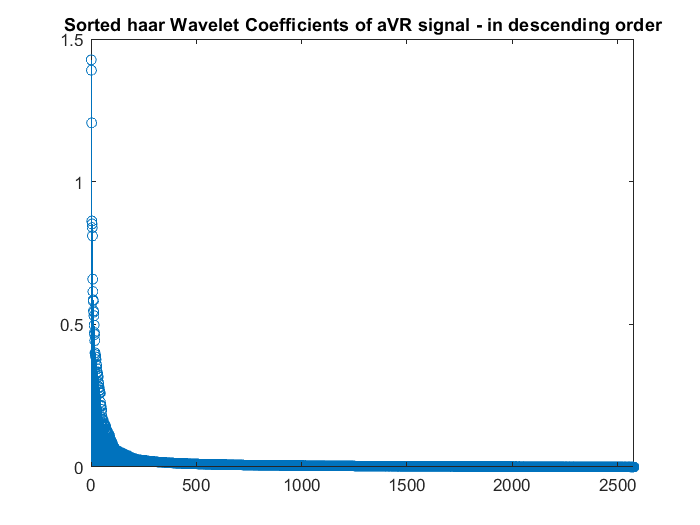

Number coefficients required to represent 99% of the energy of the signal = 138
Compression Ratio = 18.6232


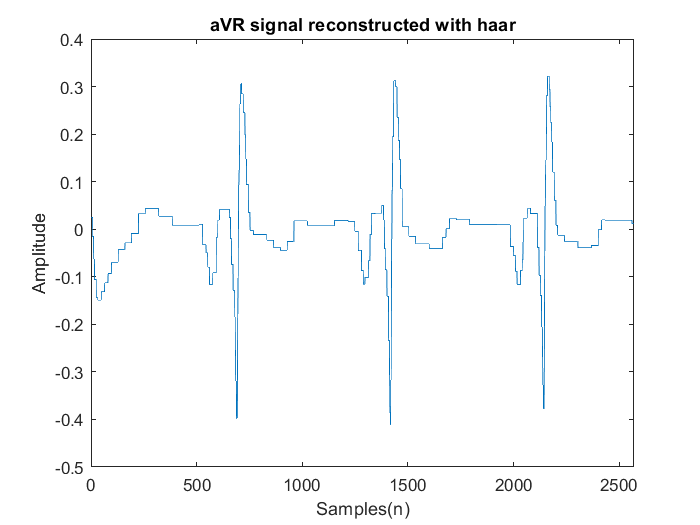

RMSE of aVR signal reconstructed with haar wavelet = 0.0095818


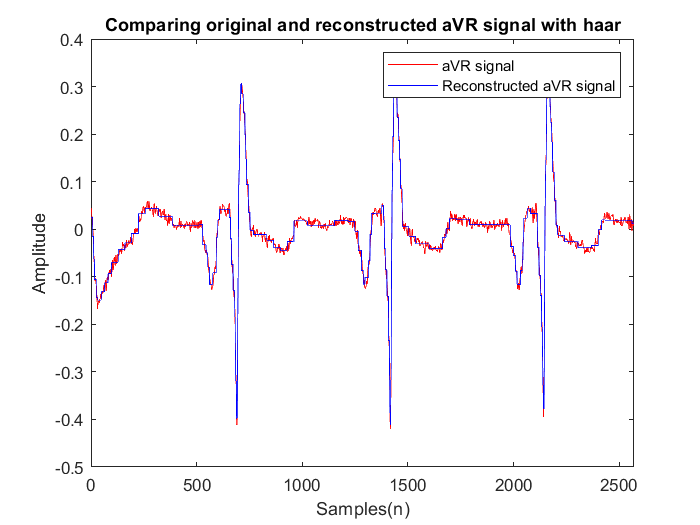

signal_compression(aVR, level, 'haar', percentage, 'aVR signal'); 

**DB9 Wavelet for aVR signal**

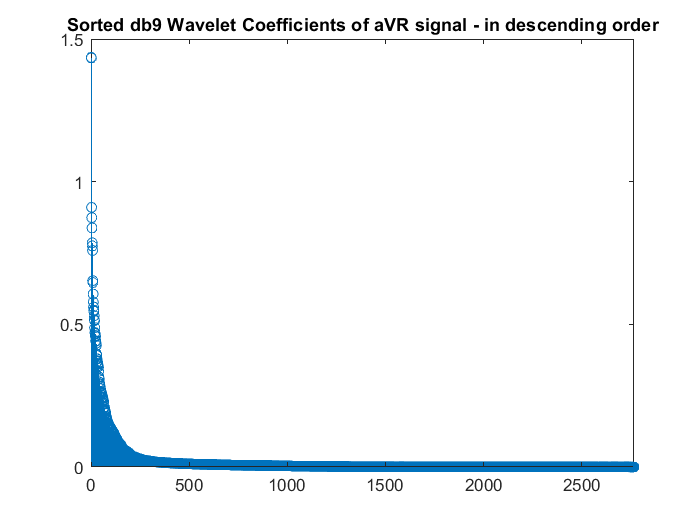

Number coefficients required to represent 99% of the energy of the signal = 161
Compression Ratio = 15.9627


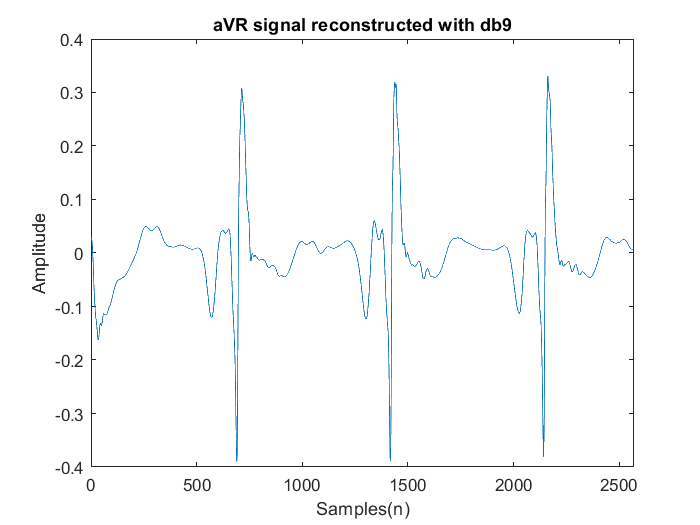

RMSE of aVR signal reconstructed with db9 wavelet = 0.0081062


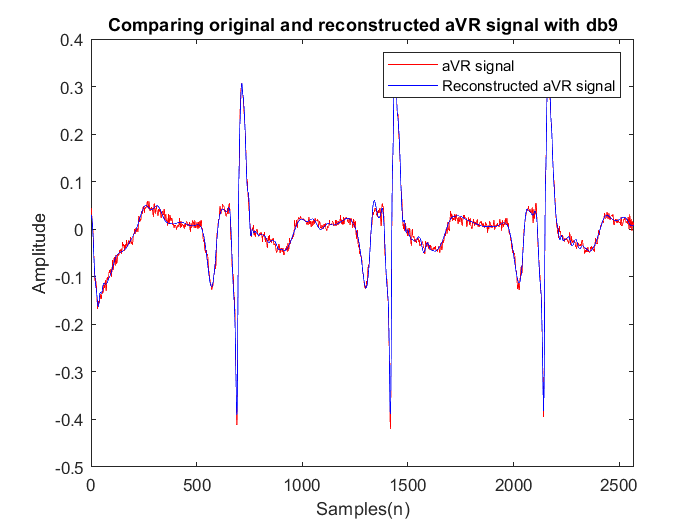

signal_compression(aVR, level, 'db9' , percentage, 'aVR signal'); 